A = [1.0 1.0 0.0 ;
0.0 1.0 0.0 ;
0.0 -1.0 1.0 ;]

A =      1     1     0
     0     1     0
     0    -1     1


% wie gut die Ergebnise aussehen hängt von condition number einer Matrix

t_cond = T_Cond;
t_cond.A = A;
condNr = t_cond.t_cond

start condition number
Elapsed time is 0.000371 seconds.


condNr =    3.732050807568877



t_lu = T_LU;
t_lu.A = A;

[L, U, P]= t_lu.t_lup

start lu decomposition
Elapsed time is 0.000067 seconds.


L =      1     0     0
     0     1     0
     0    -1     1


U =      1     1     0
     0     1     0
     0     0     1


P =      1     0     0
     0     1     0
     0     0     1



P * L * U 

ans =      1     1     0
     0     1     0
     0    -1     1


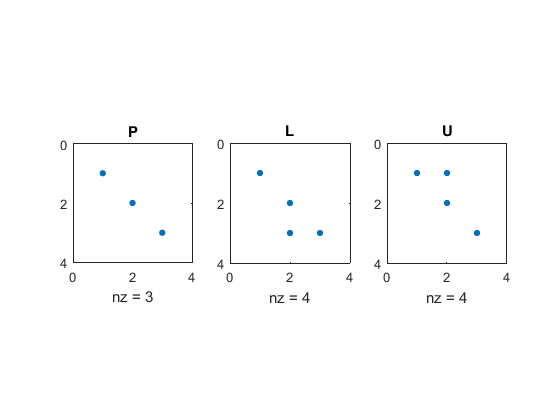


subplot(1, 3, 1)
spy(P), title('P')
subplot(1, 3, 2)
spy(L), title('L')
subplot(1, 3, 3)
spy(U), title('U')